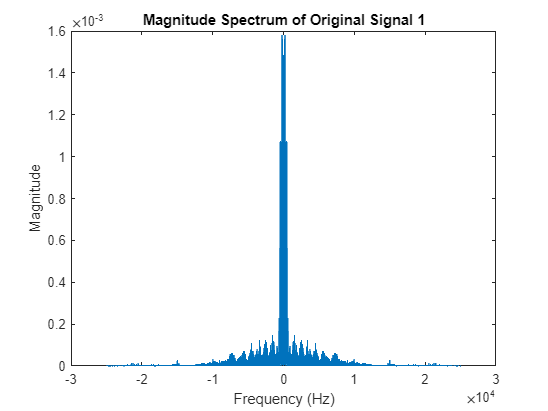

[x1, fs1] = audioread('input1.wav'); 
[x2, fs2] = audioread('input2.wav'); 


% plotting for the first original signal
N1 = length(x1);
X1 = fft(x1, N1);
f1 = (-N1/2:N1/2-1)*fs1/N1;
figure;
plot(f1, abs(fftshift(X1))/N1);
title('Magnitude Spectrum of Original Signal 1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

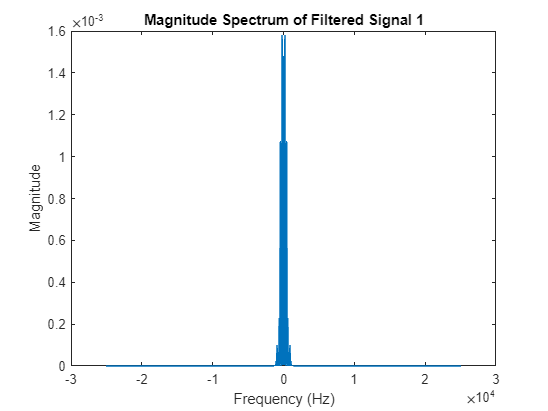


% Load the filter
load('lpf3.mat'); 

% Apply the loaded filter 
filtered_voice1 = filter(lpf3, x1);
filtered_voice2 = filter(lpf3, x2);

% plotting for the filtered signal 1
N1_filtered = length(filtered_voice1);
X_filtered1 = fft(filtered_voice1, N1_filtered);
f_filtered1 = (-N1_filtered/2:N1_filtered/2-1)*fs1/N1_filtered;
figure;
plot(f_filtered1, abs(fftshift(X_filtered1))/N1_filtered);
title('Magnitude Spectrum of Filtered Signal 1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

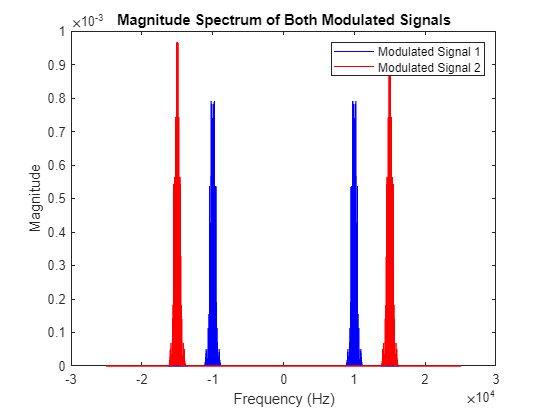



% Modulation parameters
Fc_mod1 = 10000; % 10 kHz for first signal
Fc_mod2 = 15000; % 15 kHz for second signal

% Time vectors for modulation
t1 = (0:length(filtered_voice1)-1)/fs1;
t2 = (0:length(filtered_voice2)-1)/fs1;

% Modulate both signals
modulated_signal1 = filtered_voice1 .* cos(2 * pi * Fc_mod1 * t1)';
modulated_signal2 = filtered_voice2 .* cos(2 * pi * Fc_mod2 * t2)';

% FFT for modulated signals
fft_modulated1 = fft(modulated_signal1);
fft_modulated2 = fft(modulated_signal2);





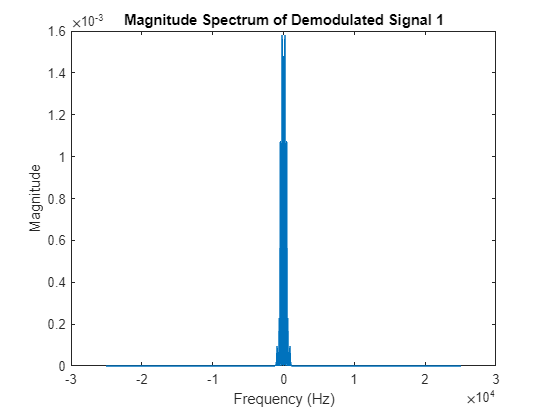

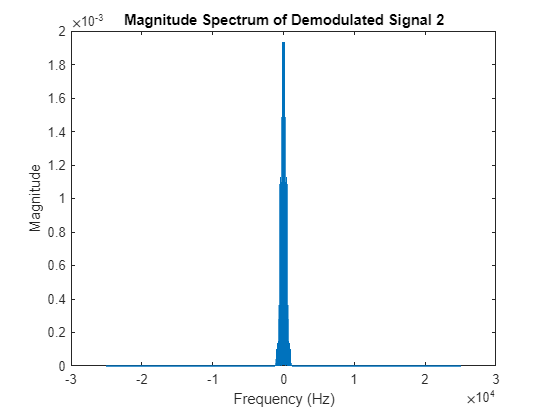

x = 1;


% Demodulate
while x ~= 0
    x = input('Choose signal to demodulate: 1 or 2 (0 to exit): ');

    switch x
        case 1
            Fc_mod = Fc_mod1; 
            t = t1; 
            modulated_signal = modulated_signal1;
        case 2
            Fc_mod = Fc_mod2; 
            t = t2; 
            modulated_signal = modulated_signal2;
        otherwise
            continue; 
    end

    if x == 1 || x == 2
        demodulated_signal = modulated_signal .* cos(2 * pi * Fc_mod * t)';
        
        demodulated_filtered_signal = 2 * filter(lpf3, demodulated_signal);
        
            N1_demodulated = length(demodulated_filtered_signal);
    f_demodulated1 = (-N1_demodulated/2:N1_demodulated/2-1)*fs1/N1_demodulated;
    figure;
    plot(f_demodulated1, abs(fftshift(fft(demodulated_filtered_signal, N1_demodulated)))/N1_demodulated);
        title(['Magnitude Spectrum of Demodulated Signal ' num2str(x)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
        % Play the demodulated signal
        sound(demodulated_filtered_signal, fs1);
    end
end